# Waste Analysis Demo

Use the ThermoeconomicModel function to make waste analysis

### **Read and create the Thermoeconomic Model**

file="D:\Documents\Termoeconomia\TaesLab\Examples\gturbo\gturbo_model.json";
model=ThermoeconomicTool(file,'Debug',false);

### Define Waste Parameters

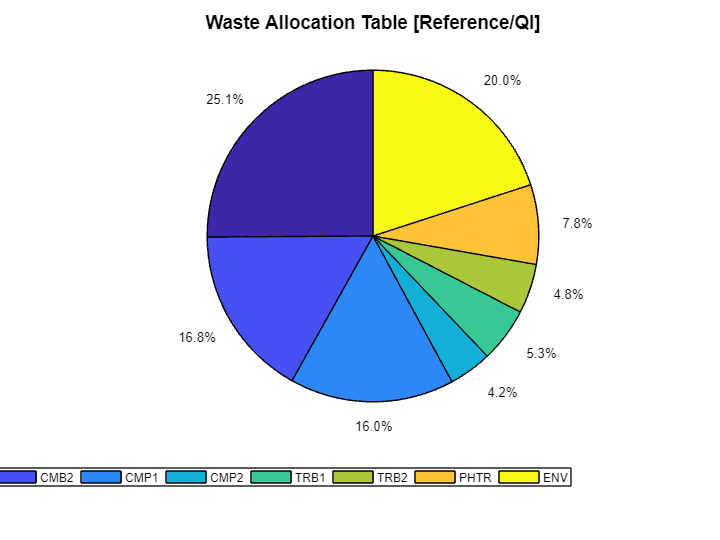

WasteFlows=convertCharsToStrings(model.WasteFlows);
WasteFlow=convertStringsToChars(WasteFlows(1));
model.setWasteType(WasteFlow,'IRREVERSIBILITY');
model.setWasteRecycled(WasteFlow,0.2);
showGraph(model,cType.Tables.WASTE_ALLOCATION,WasteFlow);

### Compute Exergy Cost

model.wasteAllocation;

Waste Definition Table

Key  Type              Recycling (%)
—————————————————————————————————————
QI   IRREVERSIBILITY        20.00
QG   IRREVERSIBILITY        20.00


Waste Allocation Table  (%)

 Key          QI        QG
———————————————————————————
 CMB1      25.10     29.00
 CMB2      16.78     29.01
 CMP1      16.02      3.66
 CMP2       4.20      4.85
 TRB1       5.31      2.37
 TRB2       4.83      2.15
 PHTR       7.75      8.96
 ENV       20.00     20.00



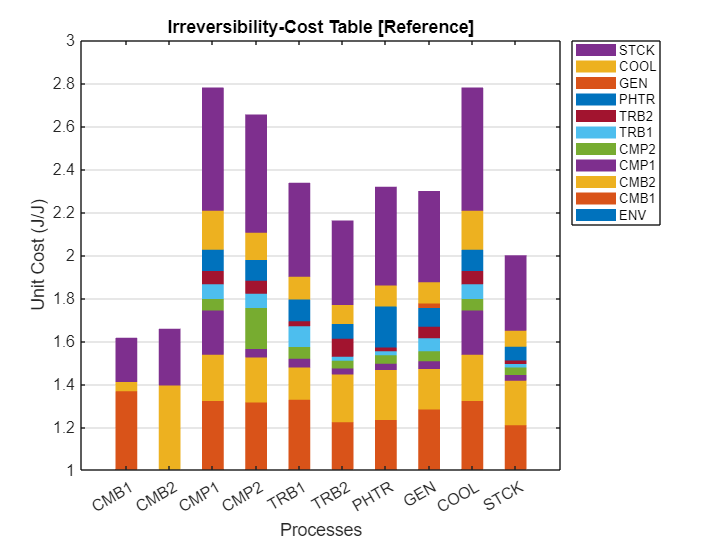

showGraph(model,cType.Tables.PROCESS_ICT);

### Recycling Analysis

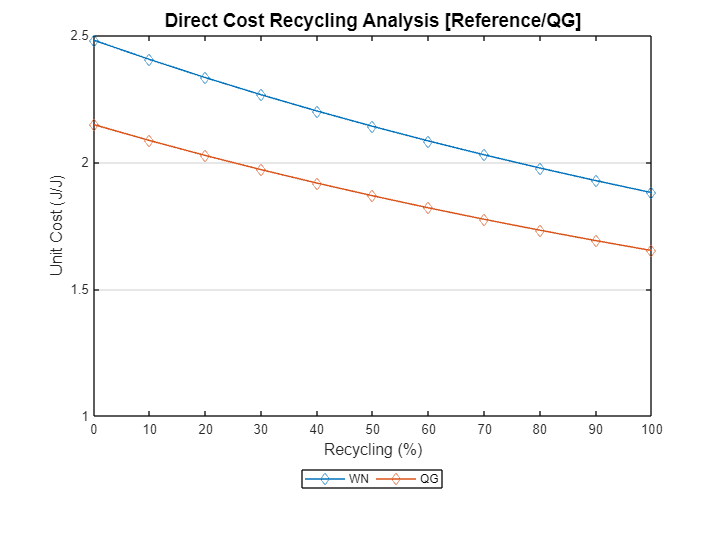

model.ActiveWaste=WasteFlow;
model.Recycling=true;
res=model.wasteAnalysis;
showGraph(res,cType.Tables.WASTE_RECYCLING_DIRECT)

printResults(res);

Waste Definition Table

Key  Type              Recycling (%)
—————————————————————————————————————
QI   IRREVERSIBILITY         0.00
QG   IRREVERSIBILITY        20.00


Waste Allocation Table  (%)

 Key          QI        QG
———————————————————————————
 CMB1      31.38     29.00
 CMB2      20.97     29.01
 CMP1      20.03      3.66
 CMP2       5.25      4.85
 TRB1       6.64      2.37
 TRB2       6.04      2.15
 PHTR       9.69      8.96
 ENV        0.00     20.00


Direct Cost Recycling Analysis (J/J)

 Recycle (%)         WN        QG
——————————————————————————————————
      0          2.4792    2.1470
     10          2.4035    2.0844
     20          2.3320    2.0254
     30          2.2645    1.9696
     40          2.2006    1.9168
     50          2.1400    1.8667
     60          2.0825    1.8192
     70          2.0279    1.7741
     80          1.9759    1.7311
     90          1.9264    1.6902
    100          1.8792    1.6512

